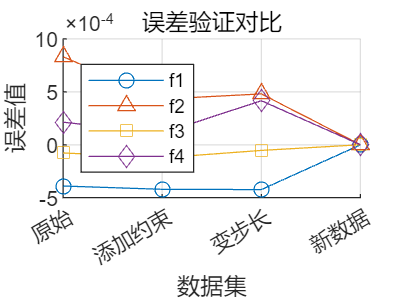

% 定义不同数据集的标签 (新增 '新数据')
clear;clc;
datasets = {'原始', '添加约束', '变步长', '新数据'};

% 对应的误差数据（4 个误差量，现在是 4 个数据集）
% 将新数据追加到对应的数组末尾
f1_errors = [-3.8996e-04, -4.2095e-04, -4.2355e-04, -1.7319e-07];
f2_errors = [ 8.3160e-04,  4.3187e-04,  4.8059e-04,  1.7632e-07];
f3_errors = [-7.7249e-05, -1.2322e-04, -5.3399e-05, -6.8930e-09];
f4_errors = [ 2.1302e-04,  1.0980e-04,  4.1602e-04, -2.0894e-08];

% 将数据集用整数索引表示作为x轴
x = 1:length(datasets);

%% 原始 4 条曲线
figure;
hold on;
plot(x, f1_errors, '-o', 'DisplayName', 'f1');
plot(x, f2_errors, '-^', 'DisplayName', 'f2');
plot(x, f3_errors, '-s', 'DisplayName', 'f3');
plot(x, f4_errors, '-d', 'DisplayName', 'f4');
hold off;

legend('show', 'Location', 'best');
grid on;
xticks(x);
xticklabels(datasets);
title('误差验证对比');
xlabel('数据集');
ylabel('误差值');


%% 方法 1: 绝对误差均值和标准差
abs_errors = abs([f1_errors; f2_errors; f3_errors; f4_errors]);  % 4×4，行=误差类型，列=数据集

mean_errors = mean(abs_errors, 1);         % 1×4，4 个数据集
std_errors  = std(abs_errors, 0, 1);       % 1×4

disp('每个数据集的绝对误差均值:');

每个数据集的绝对误差均值:


disp(mean_errors);

   1.0e-03 *

    0.3780    0.2715    0.3434    0.0001



disp('每个数据集的绝对误差标准差:');

每个数据集的绝对误差标准差:


disp(std_errors);

   1.0e-03 *

    0.3284    0.1791    0.1955    0.0001



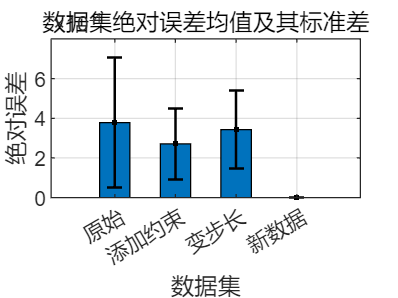


figure;
bar(mean_errors, 0.5);
hold on;
errorbar(x, mean_errors, std_errors, '.k', 'LineWidth', 1); % 注意这里加上 x
hold off;
xticks(x);
xticklabels(datasets);
title('数据集绝对误差均值及其标准差');
xlabel('数据集');
ylabel('绝对误差');
grid on;


%% 方法 2: RMSE
rmse_errors = sqrt(mean(abs_errors.^2, 1));    % 1×4

disp('每个数据集的RMSE:');

每个数据集的RMSE:


disp(rmse_errors);

   1.0e-03 *

    0.4730    0.3126    0.3828    0.0001



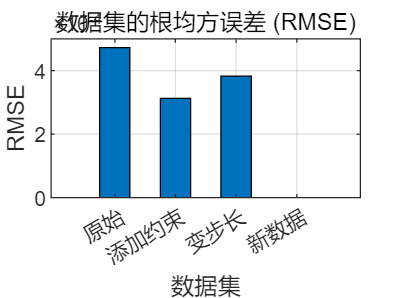


figure;
bar(rmse_errors, 0.5);
xticks(x);
xticklabels(datasets);
title('数据集的根均方误差 (RMSE)');
xlabel('数据集');
ylabel('RMSE');
grid on;


%% 方法 3: 最大偏差
max_deviation = max(abs_errors, [], 1);        % 1×4

disp('每个数据集的最大偏差:');

每个数据集的最大偏差:


disp(max_deviation);

   1.0e-03 *

    0.8316    0.4319    0.4806    0.0002



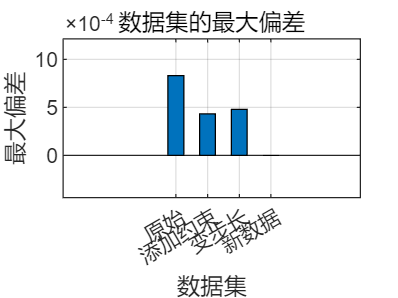


figure;
bar(max_deviation, 0.5);
xticks(x);
xticklabels(datasets);
title('数据集的最大偏差');
xlabel('数据集');
ylabel('最大偏差');
grid on;

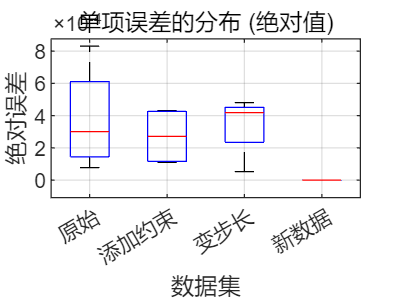


%% 方法 4: 误差分布箱线图（按“数据集”分组）
% 此时我们希望：每一个 box 代表一个“数据集”，里边包含 4 个误差值 (f1~f4)

errors_for_boxplot = abs_errors;   % 4×4：列=4个数据集 => 会画出 4 个 box

figure;
boxplot(errors_for_boxplot, 'Labels', datasets);  % Labels 数 = 4，与列数 = 4 完全一致
title('单项误差的分布 (绝对值)');
xlabel('数据集');
ylabel('绝对误差');
grid on;


%% 方法 5: ANOVA 单因素分析（比较不同“数据集”的均值是否有显著差异）
% 我们有 4×4 个数据，每一列代表一个数据集
% 做 ANOVA 时，向量长度 = 4*4 = 16
% 分组变量 group_labels 也必须是 16×1

all_errors = abs_errors(:);   % 16×1

% 生成分组标签：每个数据集中有 4 个点 => 每个标签重复 4 次
group_labels = repelem(datasets, size(abs_errors, 1))';  % 4*4=16 个标签，转成列向量 16×1

% 单因素方差分析
[p, tbl, stats] = anova1(all_errors, group_labels, 'off');
disp('ANOVA 方差分析结果:');

ANOVA 方差分析结果:


disp(tbl);

    {'来源'}    {'SS'        }    {'df'}    {'MS'        }    {'F'       }    {'p 值(F)' }
    {'组'  }    {[3.5198e-07]}    {[ 3]}    {[1.1733e-07]}    {[  2.6347]}    {[  0.0976]}
    {'误差'}    {[5.3437e-07]}    {[12]}    {[4.4531e-08]}    {0×0 double}    {0×0 double}
    {'合计'}    {[8.8635e-07]}    {[15]}    {0×0 double  }    {0×0 double}    {0×0 double}



disp(['p 值 = ', num2str(p)]);

p 值 = 0.097624


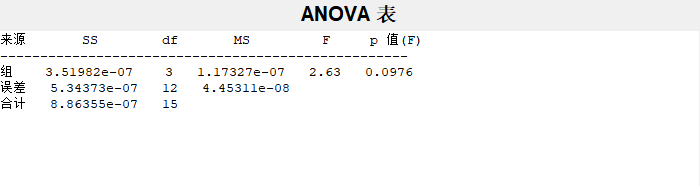


figure;
anova1(all_errors, group_labels);

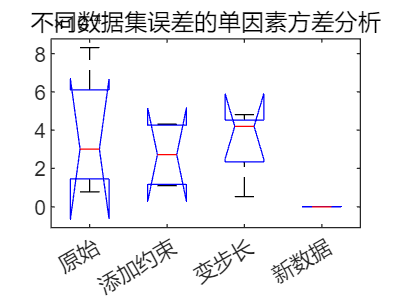

title('不同数据集误差的单因素方差分析');

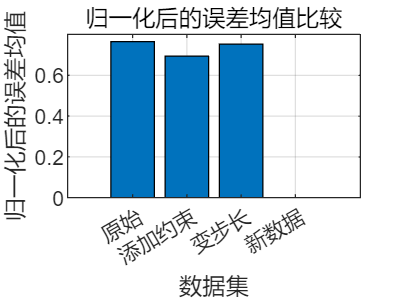


%% 方法 6: 归一化误差（对每个误差类型在四个数据集上做 min-max 归一化）
min_val = min(abs_errors, [], 2);   % 4×1，每一行一个误差类型的最小值
max_val = max(abs_errors, [], 2);   % 4×1

% 防止分母为 0（极端情况下 min == max）
range_val = max_val - min_val;
range_val(range_val == 0) = 1;

normalized_errors = (abs_errors - min_val) ./ range_val;  % 4×4

figure;
bar(x, mean(normalized_errors, 1));  % 对每个数据集求 4 个误差类型的平均“归一化值”
xticks(x);
xticklabels(datasets);
title('归一化后的误差均值比较');
xlabel('数据集');
ylabel('归一化后的误差均值');
grid on;